# **1. Rigid body Inertia moments and Reference Frame**

The proposed approach follows a method based on the research developed by [1] to determine the inertia properties of a rigid body and define a new body frame that allows the inertia matrix to be diagonalized.

## 1. Define the body frame

### 1.1. Background

A new body frame is established with the purpose of achieving a diagonalized inertia matrix. In [2], a method is introduced to transform a non-diagonal inertia matrix into a diagonal one. The procedure for this transformation is explained in detail in Section 4.4.2 of [2], where it is presented as a conventional technique within the field of linear algebra. In [2], it is assumed that the original inertia tensor follows the form of Equation (1.1):

             $I=\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & I_{\textrm{xy}}  & I_{\textrm{xz}} \\
I_{\textrm{xy}}  & I_{\textrm{yy}}  & I_{\textrm{yz}} \\
I_{\textrm{xz}}  & I_{\textrm{yz}}  & I_{\textrm{zz}} 
\end{array}\right\rbrack$ eq. (1.1)

The objective of this procedure is to find a rotation matrix called [A] in the sense that the following equation become true.

$\omega=[A]\omega '$         eq. (1.2)

**Where**

- $\omega$ : Agular rate in initial body axis frame

- $\omega$' : Angular rate in new body frame.

-  A  : Rotation matrix from old body frame to new body frame

The conversion can be calculated taking into account the rotational kinetic energy $T_{rot}$ which is described in .

$T_{rot}=\frac{1}{2}\omega^T[I]\omega
$    eq. (1.3)

And it can be rewriten as:

$T_{rot}=\frac{1}{2}([A]\omega')^T[I]([A]\omega')$      (1.4)

$2T_{rot}=([A]\omega')^T[I][A]\omega'=(\omega')^{T}[A]^T[I][A]\omega'=(\omega')^T[I']\omega'
$   (1.5)$^a$

From equation (1.5) It can be noted that the inertia tensor related to the new body frame is $\left\lbrack I^{\prime } \right\rbrack ={\left\lbrack A\right\rbrack }^T \left\lbrack I\right\rbrack \left\lbrack A\right\rbrack$.

To calculate the new Inertia tensor [I'] and the matriz rotation [A] the following procedure is followed:

- Eigen values $\lambda_i$ of the inertia matrix [I] are the principal moments of inertia of the new diagonal matrix [I'].

- The eigenvectors $e_1, e_2, e_3$ of [I] are the column vectors of the transformation matrix A.

Now, the new body frame is defined.

### 1.2. Implementation

Satellite properties measured from the geometric centrer

%%% Inertia Properties kg*m^2 (obtained from solidWorks)
I = [3131657.81,   15883.56,   82237.94;
     15883.56,   3540058.92,  -54645.58;
     82237.94,    -54645.58,  3083878.47]*1E-9; 
%%% Mass center (obtained from solidWorks)
Cm = [-0.23, -2.58, -1.44]'*1e-3;

%%% Transformation (from reference of solid to defined inertial frame)
A = rotz(90)*rotx(90);

%%% Create transformations
format long
Is = A*I*A';
Cm = A*Cm;

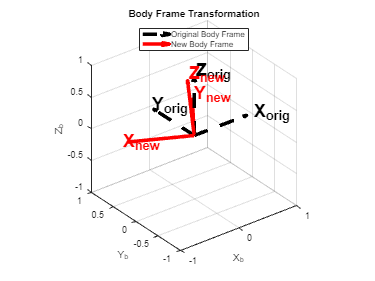


% It is necessary to perform the rotation matrix to obtain the new reference frame.
%%% To obtain the rotation Matrix A and the new inertia body frame it is used the function eig
[A, I_body] = eig(Is);
%%%CODE TO PLOT THE NEW BODY FRAME
figure
h1 = plotMainAxis(1,eye(3),'k--','orig');
h2 = plotMainAxis(1,A','r-','new');

% Add legends and plot settings
legend([h1, h2], 'Original Body Frame','New Body Frame','location','north');
title('Body Frame Transformation');
axis([-1 1 -1 1 -1 1])
xlabel('X_b')
ylabel('Y_b')
zlabel('Z_b')

%%% Show original inertia tensor
disp(Is);

   0.003083878470000   0.000082237940000  -0.000054645580000
   0.000082237940000   0.003131657810000   0.000015883560000
  -0.000054645580000   0.000015883560000   0.003540058920000



%%% Show inertia tensor regarding to new reference frame
disp(I_body);

   0.003016691758391                   0                   0
                   0   0.003192296051602                   0
                   0                   0   0.003546607390006



## 2. Inertia Elipsoid Calculation

An inertia ellipsoid, also known as inertia tensor ellipsoid, is a three-dimensional geometric shape used in mechanics and engineering to represent the distribution of mass within a rigid body. It is defined by the eigenvalues and eigenvectors of the inertia tensor of the body. The inertia tensor describes how mass is distributed in a three-dimensional object and is a crucial parameter in the analysis of its rotational motion.

### 2.1. Background

First is mandatory to explain what is momentum of inertia, inertia vector and inertia Tensor.

#### 2.1.1. Inertia Vector

In this case it is considered a system composed of several points denoted as $P_1, P_2, P_3, ... P_n$ with mass $m_1, m_2, m_3, ..., m_n$ and positions vectors denoted as $\bar r_1, \bar r_2, \bar r_3, ..., \bar r_n$. (See fig 2.1.1.)

According to [3] a inertia vector associated with a direction defined by a unitary vector $\bar u$ is defined by the following equation:

$\bar I_u = \sum^n_{k=1}m_k\bar r_k \times(\bar u \times \bar r_k)$  eq. 2.1.1

In the following code we denote a figure that depicts the proposed system and also it depicts the implementation of the equation 2.1.1.

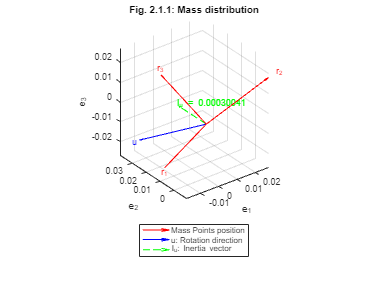

figure()
%%% Code to implement the inertia momentum if I_u
%%% Define points
%%% Position vectors
r1 = [-1, 2,-3]*1e-2;  %% position of point 1 (m)
r2 = [ 3,-1, 2]*1e-2;  %% position of point 2 (m)
r3 = [-2, 1, 3]*1e-2;  %% position of point 2 (m)
ri = [r1; r2; r3];     %% position vector
%%% Mass properties
m1=0.100;  %% mass of point 1 (g)
m2=0.150;  %% mass of point 2 (g)
m3=0.080;  %% mass of point 3 (g)
mi=[m1,m2,m3];

%%% Define the unitary vector u
u = [-1,5,-3]/norm([-1,5,-3]); %% Just examples

%%% Implement Inertia vector equation (2.1.1)
Iu = zeros(1,3);
for i = 1: size(ri,2)
    Iu=Iu+cross(mi(i)*ri(i,:),cross(u,ri(i,:)));
end

%%% PLOTS 
%%% Plot points
for i = 1: size(ri,2)
    h1 = plotVector(ri(i,:),1,'r',['r_',num2str(i)]);
    hold on
end
%%% Plot vector u
h2 = plotVector(u,5E-2,'b','u');
%%% Plot vector Iu 
h3 = plotVector(Iu,1E2,'g--',['I_u = ',num2str(norm(Iu))]);
axis equal;
% Add legends and plot settings
legend([h1, h2, h3], 'Mass Points position','u: Rotation direction','I_u: Inertia vector','Location','southoutside');
title('Fig. 2.1.1: Mass distribution');
xlabel('e_1')
ylabel('e_2')
zlabel('e_3')

fprintf('The Iu vector is: [%.4e,%.4e,%.4e] \n', Iu(1),Iu(2),Iu(3));

The Iu vector is: [5.6794e-05,2.9006e-04,-5.3752e-05] 


The momentun of inertia $I_u$ can be expressed in the componentes asociated with the three main axis denoted as $(\bar {e_1}, \bar {e_2}, \bar {e_3})$.

$\bar{I_u}=\bar{I_1}u_1+\bar{I_2}u_2+\bar{I_3}u_3$                   (eq. 2.1.2)

Where $u_1$, $u_2$, and $u_3$ are the unitary vectors in direction of $\bar{e_1}$, $\bar{e_2}$, and $\bar{e_3}$. According to [3] it can be considered several direction of $\bar u$ to obtain an idea about mass distribution for the body under study.

#### 2.1.2. Momentum of Inertia

We can make a projection of the inertia vector $\bar I_u$ over the direction defined by $\bar u$ and of its perpendicular plane denoted as $\bar v$. The projection of $\bar {I_u}$ over $\bar u$ vector is denoted as $I_{uu}$ according to (2.1.3) and is called momentum of inertia.

$I_{uu}=\bar {I_u}  \cdot \bar u = \sum m_k  \left[ r^2_k-(\bar {r_k}\cdot\bar u)^2 \right ]$   (eq. 2.1.3)

The projection of vector $\bar {I_u}$ over the direction $\bar v$  is known as inertia product and is denoted as eq. (2.1.4)

$I_{uv}=\bar{I_u}\cdot\bar v=-\sum m_k(\bar{r_k}\cdot\bar u)(\bar {r_k}\cdot\bar{v})$  (eq. 2.1.4)

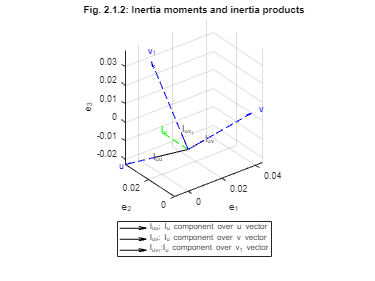

figure()
%%% Define a vector v perpendicular a u
v  = [u(2), -u(1), 0];
v  = v/norm(v);
%%% Define a vector v1 perpendicular to u and v
v1 = cross(v,u);
v1 = v1/norm(v1);

%%% Calculate moments and product of inertia
Iuu = Iu*u' ;
Iuv = Iu*v' ;
Iuv1= Iu*v1';

%%% Plot vector u, v and v1 whit a scale
h1 = plotVector(u,5E-2,'b--','u');
hold on
h2 = plotVector(v,5E-2,'b--','v');
h3 = plotVector(v1,5E-2,'b--','v_1');

%%% Plot vector Iu whit scale
h4 = plotVector(Iu,1E2,'g--','I_u');

%%% Plot vector Iuu whit scale
Iuu_v=Iuu*u;
h5 = plotVector(Iuu_v,1E2,'k','I_{uu}');
%%% Plot vector Iuv whit scale
Iuv_v=Iuv*v;
h6 = plotVector(Iuv_v,1E2,'k','I_{uv}');
%%% Plot vector Iuv1 whit scale
Iuv1_v=Iuv1*v1;
h7 = plotVector(Iuv1_v,1E2,'k','I_{uv_1}');

axis equal;
title('Fig. 2.1.2: Inertia moments and inertia products');
% Add legends and plot settings
legend([h5, h6, h7], 'I_{uu}: I_u component over u vector','I_{uv}: I_u component over v vector','I_{uv_1}:I_u component over v_1 vector','Location','southoutside');
xlabel('e_1');
ylabel('e_2');
zlabel('e_3');

fprintf('Iuu = %.4e;\nIuv = %.4e;\nIuv1 = %.4e;\n',Iuu,Iuv,Iuv1);

Iuu = 2.6280e-04;
Iuv = 1.1258e-04;
Iuv1 = 9.2253e-05;


#### 2.1.3. Inertia Tensor 

The equations (2.1.3) and (2.1.4) can be agrupped in one equation denoted as (2.1.5).

$I_{ij}=\sum m_k\left[r^2_k\delta_{ij}-\left(\bar {r_k}\cdot\bar {u_i}\right)\left(\bar {r_k}\cdot\bar {u_j}\right)\right]$   (2.1.5)

Where $\delta_{ij}$ is Kronecker delta function and the inertia tensor is defined as $I$.

$I=\left\lbrack \begin{array}{ccc}
I_{11}  & I_{12}  & I_{13} \\
I_{21}  & I_{22}  & I_{23} \\
I_{31}  & I_{32}  & I_{33} 
\end{array}\right\rbrack$     (2.1.6)

 In the following code we show an implementation of the equation (2.1.5) regarding to frame $\left[ \bar{e_1},  \bar{e_2}, \bar{e_3}\right ]$ 

% Define unitary vectors (Fig. 2.1.2)
e = eye(3);

% Calculate Inertia tensor I_ij acoording to reference frame U
I = zeros(3, 3);
for i = 1:3
    for j = 1:3
        term_sum = 0;
        for k = 1:size(ri, 1)
            r  = ri(k, :);
            ui = e(i,:);
            uj = e(j,:);
            term = r * r' * (i == j) - (r * ui') * (r * uj');
            term_sum = term_sum + term * mi(k);
        end
        I(i, j) = term_sum;
    end
end

%%% Inertia tensor I_ij:
disp(I);

   1.0e-03 *

   0.285000000000000   0.081000000000000  -0.072000000000000
   0.081000000000000   0.399000000000000   0.066000000000000
  -0.072000000000000   0.066000000000000   0.240000000000000



According to [2] in secction 4.4.1, the inertia vector $I_u$can be described by equation (2.1.7).

$I_u=\bar{u}  \bar I$ (2.1.7)

Iu_new = u*I;
fprintf('Iu calculado anteriormente: [%.4e,%.4e,%.4e] \n',Iu(1),Iu(2),Iu(3));

Iu calculado anteriormente: [5.6794e-05,2.9006e-04,-5.3752e-05] 


fprintf('Iu calculado por formula (2.1.7): [%.4e,%.4e,%.4e] \n',Iu_new(1),Iu_new(2),Iu_new(3))

Iu calculado por formula (2.1.7): [5.6794e-05,2.9006e-04,-5.3752e-05] 


Additionally we can calculate the inertia tensor regarding to vectors $(\bar u, \bar v, \bar {v_1})$ this is shown in the following code.

% Define unitary vectors (Fig. 2.1.2)
e = [u; v; v1];

% Calculate Inertia tensor I_ij acoording to reference frame U
I = zeros(3, 3);
for i = 1:3
    for j = 1:3
        term_sum = 0;
        for k = 1:size(ri, 1)
            r  = ri(k, :);
            ui = e(i,:);
            uj = e(j,:);
            term = r * r' * (i == j) - (r * ui') * (r * uj');
            term_sum = term_sum + term * mi(k);
        end
        I(i, j) = term_sum;
    end
end

%%% Inertia tensor I_ij:
disp(I);

   1.0e-03 *

   0.262800000000000   0.112576303793579   0.092253029969002
   0.112576303793579   0.320538461538461  -0.000663121030633
   0.092253029969002  -0.000663121030633   0.340661538461538



We can notice that the first row of the inertia tensor has te components of $I_{uu}, I_{uv}$ and $ I_{uv_1}$ 

fprintf('Iuu = %.4e; Iuv = %.4e; Iuv1 = %.4e;\n',Iuu,Iuv,Iuv1);

Iuu = 2.6280e-04; Iuv = 1.1258e-04; Iuv1 = 9.2253e-05;


fprintf('I(1,1) = %.4e; I(2,1) = %.4e; I(3,1) = %.4e;\n',I(1,1),I(2,1),I(3,1));

I(1,1) = 2.6280e-04; I(2,1) = 1.1258e-04; I(3,1) = 9.2253e-05;


Therefore, in case that we choose the coord axis denoted by $(\bar u, \bar v, \bar {v_1})$ the inertia tensor is described by equation (2.1.8). Here, we can notice that the Inertia vector $\bar{I_u}$ regarding to $(\bar u, \bar v, \bar {v_1})$ reference frame is $[I_{uu},I_{uv},I_{uv_1}]$.

$I=\left\lbrack \begin{array}{ccc}
I_{\textrm{uu}}  & I_{\textrm{uv}}  & I_{uv_1 } \\
I_{\textrm{vu}}  & I_{\textrm{vv}}  & I_{vv_1 } \\
I_{v_1 u}  & I_{v_1 v}  & I_{v_1 v_1 } 
\end{array}\right\rbrack$    (2.1.8)

### 2.1.4. Inertia momentum at any Direction

To calculate the momentum of inertia with respect to any vector $\bar u$ denoted by ($J_u
$) , it is necessary to obtain the component of the inertia vector $I_u$ along the unit vector $\bar u$. This can be calculated using equation (eq. 2.1.3) and (2.1.7) to use the inertia tensor $[I]$ according to equation (2.1.9) . 

$J_u=I_{uu} = I_{u} \bar u=\bar u^T [I] \bar u$  (2.1.9)

 Due to $\bar u$ is in direction of body rate vector ($\hat \omega$), the components of $\bar u$ will be $\left [ \frac{\omega_1}{\omega},\frac{\omega_2}{\omega},\frac{\omega_3}{\omega} \right]$ where $\omega 
$ is the magnitude of $\hat \omega$ and $\omega_1$, $\omega_2$ and $\omega_3$ are its components over the reference frame denoted by $(\bar {e_1}, \bar {e_2}, \bar {e_3})$. Taking into account equation (2.1.9) and developed the vectorial product we can obtain equation (2.1.10).

$J_{u} = \left(  \frac{\omega_1}{\omega}\right)^2I_{11}+\left(  \frac{\omega_2}{\omega}\right)^2I_{22}+\left(  \frac{\omega_3}{\omega}\right)^2I_{33}-2 \left(  \frac{\omega_2}{\omega}\right) \left(  \frac{\omega_3}{\omega}\right)I_{32}-2 \left(  \frac{\omega_1}{\omega}\right) \left(  \frac{\omega_3}{\omega}\right)I_{13}-2 \left(  \frac{\omega_1}{\omega}\right) \left(  \frac{\omega_2}{\omega}\right)I_{21}$       (2.1.10)

In case that we have choose the principal axes in the way that inertia tensor becomes diagonal the above equation becomes (2.1.11)

$J_{\xi} = \left(  \frac{\omega_1}{\omega}\right)^2I_1+\left(  \frac{\omega_2}{\omega}\right)^2I_2+\left(  \frac{\omega_3}{\omega}\right)^2I_3$  (2.1.11)

Here, [2] makes a definition of $u_1
$=$\omega_1/\omega$, $u_2
$=$\omega_2/\omega$, $u_3$=$\omega_3/\omega$, which are the direction cosines of the vector $\hat \omega$. The eq (2.1.11) becomes like (2.1.12).

$J_{u} = u_1^2 I_1+u_2^2I_2+u_3^2I_3$   (2.1.12)

#### **2.1.5. Inertia Ellipsoid Definition**

The inertia ellipsoid is the geometric locus of points defined by the position vector $\bar {OP}$ described by equation (2.1.13).

$\bar {OP} = \frac{1}{\sqrt{J_u}}\bar u$   (2.1.13)

Where:

- $\bar u$:  unit vector of the line containing $\bar {OP}$.

- $J_u$: Inertia moment with respect to $\bar u$.

 We can denote vector $\bar {OP}$ like $\bar r
$. Therefore vector eq (2.1.13) becomes


$$ \bar{OP}=\bar r = \frac{1}{\sqrt{J_u}}\bar u$$


$\bar u = \bar r \sqrt{J_u}$     (2.1.14)

Remplacing (2.1.9) with (2.1.14)


$$J_u=\bar r \sqrt{J_u} [I]\bar r \sqrt{J_u} $$


$1=\bar r [I] \bar  r$   (2.1.15)

Knowing that $\bar r = (x \bar i + y \bar j + z \bar k)$, $\bar u =( u_1\bar i + u_2\bar j + u_3\bar k)$,  we can find the following relationships: $u_1=x\sqrt{J_u}, u_2=2\sqrt{J_u}$ and $u_3=z\sqrt{J_u}$. Developing the inertia product of eq (2.1.15) and asuming that a reference frame was choose to eliminate inertia products of the inertia tensor, we can obtain equation (2.1.16).

$I_{xx}x^2+I_{yy}y^2+I_{zz}z^2 = 1$   (2.1.16)

Equation (2.1.16) represents an elipse which is denominated inertia elipsoid whit the main axis as $\frac{1}{\sqrt{I_{xx}}}, \frac{1}{\sqrt{I_{yy}}}$ and $\frac{1}{\sqrt{I_{zz}}}$ in the x, y and z axis. 

#### 2.1.6. Inertia elipsoid calculated for the Satellite

The following code presents the computed inertia tensor for the Satellite in the original body frame and the new body frame that makes that inertia tensor becomes diagonal.

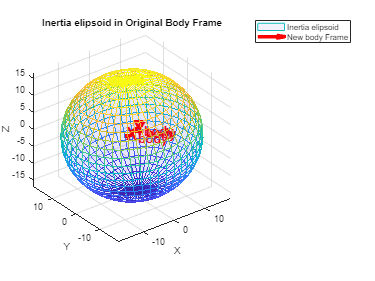

% Crear un conjunto de puntos para muestrear el elipsoide
[u,v] = meshgrid(linspace(0,2*pi,50),linspace(0,pi,25));
x = 1/(sqrt(I_body(1,1)))*sin(v).*cos(u);
y = 1/(sqrt(I_body(2,2)))*sin(v).*sin(u);
z = 1/(sqrt(I_body(3,3)))*cos(v);

% Transformar los puntos utilizando los vectores propios
ellipsoid_points = A * [x(:)'; y(:)'; z(:)'];

% Reorganizar los puntos para usar con surf
x_surf = reshape(ellipsoid_points(1,:), size(x));
y_surf = reshape(ellipsoid_points(2,:), size(y));
z_surf = reshape(ellipsoid_points(3,:), size(z));

% Crear una figura y trazar el elipsoide utilizando surf
figure;
h1=surf(x_surf, y_surf, z_surf, 'FaceColor', 'blue', 'EdgeColor', 'flat', 'FaceAlpha', 0.05);
axis equal
hold on
h2=plotMainAxis(2,A','r-','body');
% Configurar los ejes y la vista
axis equal;
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Inertia elipsoid in Original Body Frame');
legend([h1, h2], 'Inertia elipsoid','New body Frame');
% Ajustar la vista para mostrar el elipsoide claramente
view(3);

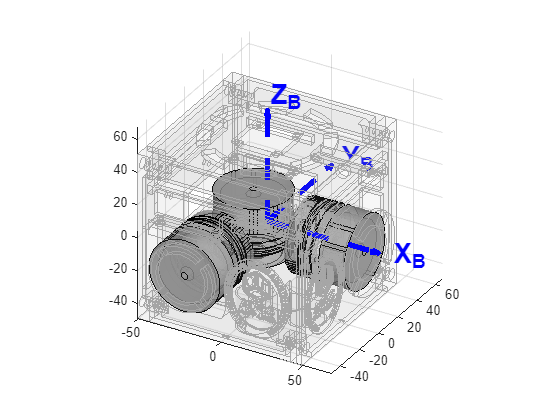

fig1=figure();
handles=axes;

rw1 = importGeometry('3dModel\ADCS_Asembbly - E1-1 RW-1.STL');
rw2 = importGeometry('3dModel\ADCS_Asembbly - E1-1 RW-2.STL');
rw3 = importGeometry('3dModel\ADCS_Asembbly - E1-1 RW-3.STL');

base = importGeometry('3dModel\ADCS_Asembbly - E1-1 Base-1.STL');
top  = importGeometry('3dModel\ADCS_Asembbly - E1-1 Top-2.STL');

L1 = importGeometry('3dModel\ADCS_Asembbly - E1-1 L1-1.STL');
L2 = importGeometry('3dModel\ADCS_Asembbly - E1-1 L2-1.STL');
L3 = importGeometry('3dModel\ADCS_Asembbly - E1-1 L3-1.STL');
L4 = importGeometry('3dModel\ADCS_Asembbly - E1-1 L4-1.STL');

motor1 = importGeometry('3dModel\ADCS_Asembbly - E1-1 Motor-1.STL');
motor2 = importGeometry('3dModel\ADCS_Asembbly - E1-1 Motor-2.STL');
motor3 = importGeometry('3dModel\ADCS_Asembbly - E1-1 Motor-3.STL');

a=pdegplot(L1,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
a=pdegplot(L2,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
a=pdegplot(L3,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
a=pdegplot(L4,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
a=pdegplot(top ,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
a=pdegplot(base,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
pdegplot(rw1,"FaceLabels","off","FaceAlpha",0.8); hold on;
pdegplot(rw2,"FaceLabels","off","FaceAlpha",0.8); hold on;
pdegplot(rw3,"FaceLabels","off","FaceAlpha",0.8); hold on;
pdegplot(motor1,"FaceLabels","off","FaceAlpha",0.5); hold on;
pdegplot(motor2,"FaceLabels","off","FaceAlpha",0.5); hold on;
pdegplot(motor3,"FaceLabels","off","FaceAlpha",0.5); hold on;

delete(findobj(handles, 'type', 'Quiver')); delete(findobj(handles, 'type', 'Text'));

h = plotMainAxis(75,eye(3),'b--','B');

h2 = plot3(Cm(1)*1E3,Cm(2)*1E3,Cm(3)*1E3,'r*','MarkerSize',5,'LineWidth',5);

Unrecognized function or variable 'Cm'.

xlim([-60 60]); ylim([-60 60]); zlim([-60 60]); grid on;
xlabel('X(mm)'); ylabel('y(mm)'); zlabel('Z(mm)');

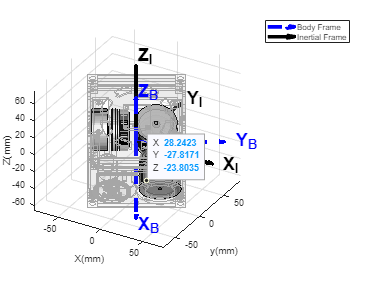

figure()
handles=axes;
%%%Rotation Matrix
A=rotz(-60)*roty(30);
a=pdegplot(L1,"FaceLabels","off","FaceAlpha",0.05);hold on; 
h=a(2);set(h,'Color',[0.65,0.65,0.65]);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(L2,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
h=a(2);set(h,'Color',[0.65,0.65,0.65]);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(L3,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
h=a(2);set(h,'Color',[0.65,0.65,0.65]);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(L4,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
h=a(2);set(h,'Color',[0.65,0.65,0.65]);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(top ,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
h=a(2);set(h,'Color',[0.65,0.65,0.65]);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(base,"FaceLabels","off","FaceAlpha",0.05);hold on; h=a(2);set(h,'Color',[0.65,0.65,0.65]);
h=a(2);set(h,'Color',[0.65,0.65,0.65]);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(rw1,"FaceLabels","off","FaceAlpha",0.8); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(rw2,"FaceLabels","off","FaceAlpha",0.8); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(rw3,"FaceLabels","off","FaceAlpha",0.8); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(motor1,"FaceLabels","off","FaceAlpha",0.5); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(motor2,"FaceLabels","off","FaceAlpha",0.5); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

a=pdegplot(motor3,"FaceLabels","off","FaceAlpha",0.5); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=A*data;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(A*h1.Vertices')';

drawnow;

delete(findobj(handles, 'type', 'Quiver')); delete(findobj(handles, 'type', 'Text'));

h_body = plotMainAxis(100,eye(3),'k-','I');
h_inertial = plotMainAxis(100,A','b--','B');
cm_rot = A*Cm*1E3;
%h2 = plot3(cm_rot(1),cm_rot(2),cm_rot(3),'r*','MarkerSize',5,'LineWidth',5);
%xlim([-60 60]); ylim([-60 60]); zlim([-60 60]); 
grid on;
xlabel('X(mm)'); ylabel('y(mm)'); zlabel('Z(mm)');
legend([h_inertial,h_body],'Body Frame', 'Inertial Frame')

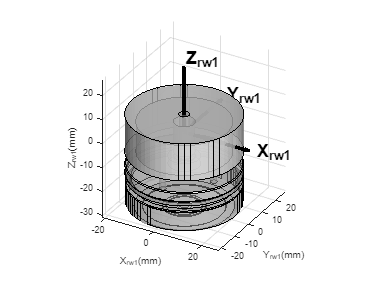

figure()
cg = [-20.8 20.8 -4.25]';
handles=axes;
a=pdegplot(rw3,"FaceLabels","off","FaceAlpha",0.8); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=data-cg;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(h1.Vertices'-cg)';

a=pdegplot(motor2,"FaceLabels","off","FaceAlpha",0.5); hold on; h=a(2);
data=[h.XData;h.YData;h.ZData]; n=data-cg;
h.XData=n(1,:); h.YData=n(2,:); h.ZData=n(3,:); h1=a(1); h1.Vertices=(h1.Vertices'-cg)';
delete(findobj(handles, 'type', 'Quiver')); delete(findobj(handles, 'type', 'Text'));

h_body = plotMainAxis(30,eye(3),'k-','{rw1}');

xlabel('X_{rw1}(mm)'); ylabel('Y_{rw1}(mm)'); zlabel('Z_{rw1}(mm)');

%legend([h_inertial,h_body],'Body Frame', 'Inertial Frame')


## Program Functions

function h = plotMainAxis(sizel,A,style,labelStyle)
%   plotMainAxis(sizel,A,style,labelStyle): plots the X, Y, and Z axes in a
%   3D coordinate system with arrows and labels. The length of the arrows
%   is determined by sizel.
%
%   Input:
%   - sizel: The length of the arrows representing the axes.
%   - A: Rotation matrix
%   - style: Line style
%   - labelStyle: Label style
%
%   Example:
%   plotMainAxis(1) plots the main axes with arrows of length 1.

% Define the coordinates and labels for the axes
axes   = {['X_{',labelStyle,'}'], ['Y_{',labelStyle,'}'], ['Z_{',labelStyle,'}']};
coords = sizel * A * eye(3);

% Plot the axes with arrows and labels
for i = 1:3
    h=quiver3(0, 0, 0, coords(i, 1), coords(i, 2), coords(i, 3), style);
    set(h,'LineWidth',4);
    h1=text(coords(i, 1), coords(i, 2), coords(i, 3), axes{i}, 'Color', style(1));
    set(h1,'FontSize',20,'FontWeight','bold');
    hold on
end

% Set equal axis scales and display grid
axis equal
grid on
end

function h = plotVector(v,scale,style,label)
h = quiver3(0, 0, 0, v(1)*scale, v(2)*scale, v(3)*scale, style);
text(v(1)*scale, v(2)*scale, v(3)*scale, label,'Color',style(1))
% Set equal axis scales and display grid
axis equal
grid on
end

## Footnote

a. The matrix transposition can be distributed due to A and $\omega$ are diagonal symetric matrix. 

## **Bibliograpy**

[1] Yoon, H., Seo, H. H., & Choi, H. T. (2014). Optimal uses of reaction wheels in the pyramid configuration using a new minimum infinity-norm solution. *Aerospace Science and Technology*, *39*, 109-119.

[2] Sidi, M. J. (1997). *Spacecraft dynamics and control: a practical engineering approach* (Vol. 7). Cambridge university press.

[3] [5.2b. Elipsoide de inercia. - YouTube](https://www.youtube.com/watch?v=OrGo33sSGw0&ab_channel=V%C3%ADdeosdocentesdeIsraelCa%C3%B1am%C3%B3nValera)